%Get the data
readings = readtable("readings.csv");
output_ar = table2array(readings);
%Convert the data from voltage to distance readings
dist_data = 67.8 - 0.0924.*reshape(output_ar',1,[])

dist_data =    59.3916   59.8536   60.5004   60.7776   62.2560   62.3484   64.3812   64.4736   66.5064   67.1532   67.1532   67.1532   67.1532   67.1532   66.9684   65.8596   66.9684   67.1532   66.9684   66.9684   67.1532   66.9684   67.1532   67.1532   67.1532   66.9684   66.9684   67.1532   66.9684   67.1532   67.1532   67.1532   67.1532   67.1532   66.2292   66.9684   66.7836   63.2724   54.5868   51.0756   49.5048   52.7388   57.5436   58.5600   58.4676   56.7120   56.2500   54.0324   50.9832   47.3796


%Initialize arrays containing the angle data
thetaz = linspace(60,120,61);
thetax = linspace(60,80,10);
thetax = repelem(thetax, 61)

thetax =     60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60


thetaz = [thetaz, thetaz, thetaz, thetaz, thetaz, thetaz, thetaz, thetaz, thetaz, thetaz, thetaz]

thetaz =     60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109


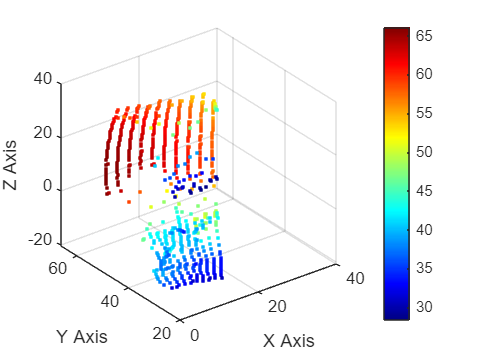

%Get length of theta arrays for later use and initialize coordinate vecors
xlength = length(thetax);
ylength = length(thetaz);
xcoords = [];
ycoords = [];
zcoords = [];
distances = dist_data;
%Iterates through angle and distance vectors simultaneosly
for i = 1:xlength
%Define the current distance of the point we are working with
current_dist = distances(i);
%Calculates x and y coordinates
x_point = current_dist*cosd(thetax(i))*sind(thetaz(i));
y_point = current_dist*sind(thetax(i))*sind(thetaz(i));
%Negates x_point if it is an obtuse angle
if thetax(i) > 90
x_point = -x_point;
end
%Append coordinate vectors
xcoords = [xcoords, x_point];
ycoords = [ycoords, y_point];
zcoords = [zcoords, current_dist*cosd(thetaz(i))];
end
%Plot the data on a heatmap
scatter3(xcoords, ycoords, zcoords, 36, ycoords, '.')
colorbar
colormap('jet')
xlabel('X Axis')
ylabel('Y Axis')
zlabel('Z Axis')